syms x
y = x+2*cos(x)

$$y = x+2\,\cos\left(x\right)$$

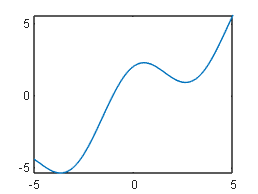

fplot(y)

x1 = input('Enter the value of x1, valor minimo \n');
x2 = input('Enter the value of x2, valor maximo \n');

if subs(y, x1)* subs(y, x2) > 0
    fprintf('Não possui sinais contrarios');
    return
end

if subs(y, x1) == 0
    fprintf('x1 é uma raíz')
    retun
elseif subs(y, x2) == 0
    fprintf('x2 é uma raíz')
    return
end


for i = 1:100
    xh = (x1 + x2)/2;
    if subs(y, x1)*subs(y, xh) < 0
        x2 = xh;
    else
        x1 = xh;
    end
    if abs(subs(y, x1)) < 1.0E-6
        break
    end
end

fprintf('A raiz é %f \n O número de bisseções é %d', x1, i)

A raiz é -1.029867 
 O número de bisseções é 23

eqn = x+2*cos(x) == 0

$$eqn = x+2\,\cos\left(x\right)=0$$

a = vpasolve(eqn, x)

$$a = -1.0298665293222588276021185168738$$